# **第五章 支持向量机（SVM）**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## 5.1 支持向量机简介

        支持向量机（Support Vector Machine, SVM）是一种强大的监督学习算法，主要用于分类和回归分析。它在解决小样本、非线性以及高维模式识别中表现出了很好的泛化能力。

        SVM最初被设计为一个线性分类器，用于在特征空间中找到一个分割超平面，以便能够将不同的类别分开。如图1所示，在二维平面上有两类样本（分别用实心点和空心点表示），理论上存在无穷多条线均可以将两类样本正确地分开（只要在图中所示的直线附近，且与直线平行或小角度倾斜）。SVM的想法是在这无穷多条线中选择一条“最好”的直线，因此，SVM本质上也是一个优化问题，而且是一个带有约束的优化问题，约束条件便是直线能够将所有的样本正确地分开。那么，作为一个优化问题，我们通常最为关心的是目标函数，SVM是怎样考虑与设计的呢？

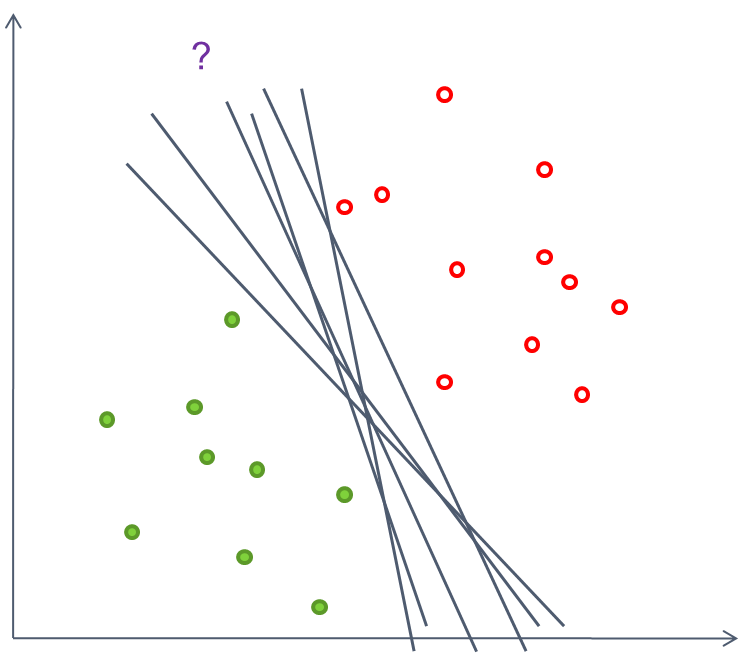

图1 SVM基本思想示意图

        为了衡量分类直线的优劣，SVM中定义了如下三个概念：

- **样本点到分类直线的距离。**已知分类直线的方程，以及样本点的坐标，根据初中几何学过的点到直线距离的计算公式，可以求出每个样本点到分类直线的距离。

- **样本点集合到分类直线的距离。**针对每个类别，找出该类别中距离分类直线距离最短的距离，并将之作为该类别的样本点集合到分类直线的距离。

- **间隔：**两类样本点集合到分类直线的距离之和。间隔越大，分类直线越“优”。

        根据上述概念，图2所示的两条分类直线中，显然左侧的分类直线要优于右侧的分类直线。同时，我们不难发现，当训练集样本点给定后，决定分类直线位置和方向的并不是全部的样本，而仅是一小部分处于类别边缘的样本，SVM中将这一小部分样本称之为“支持向量”（Support Vectors）。这也是许多资料里提到“SVM适合小样本学习”的原因。

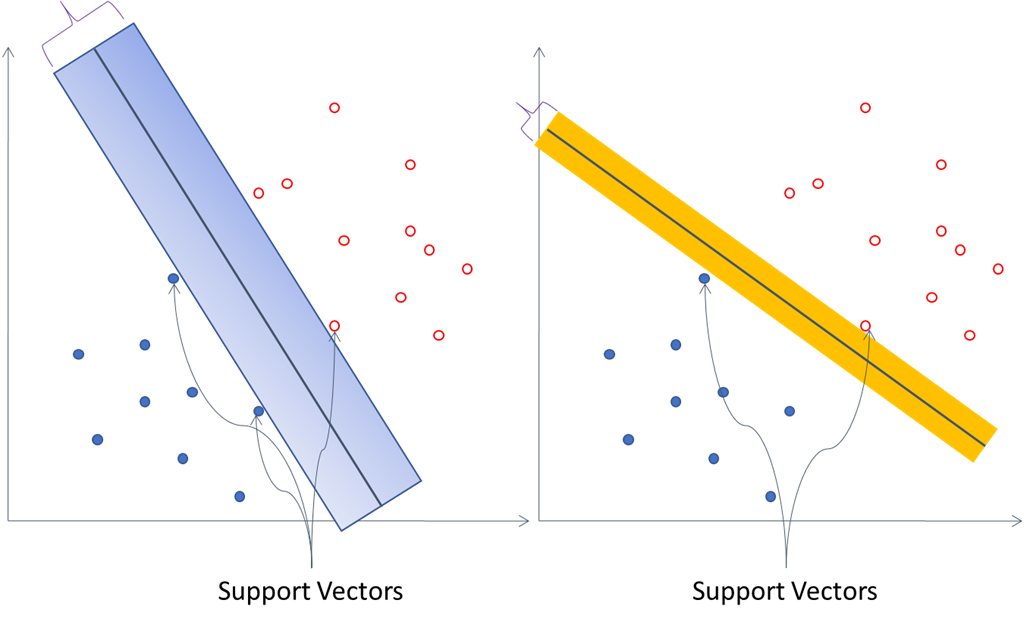

图2  支持向量示意图

        用数学语言描述上述带约束优化问题，可以得到：

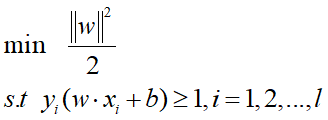

        为了更高效地求解该优化问题，SVM利用对偶原理将上述带有不等式约束的极小值优化问题转化为等价的带有等式约束的极大值优化问题，如下所列：

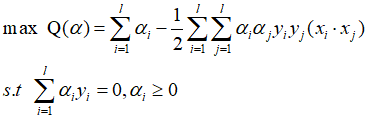

        如图3所示，若在原始空间中无法找到一条分类直线将训练集样本正确地分开，那么应该怎么办呢？SVM给出了一个非常巧妙的解决思路：先利用核函数将原始的低维输入特征映射到一个高维的特征空间，然后在高维空间里找到一个分类平面或曲面将训练集样本正确地分开。核函数除了实现特征空间的维度变换外，还有一个很重要的性质：计算量并不会随着维度上升而增加，而是保持原始低维空间的计算量。

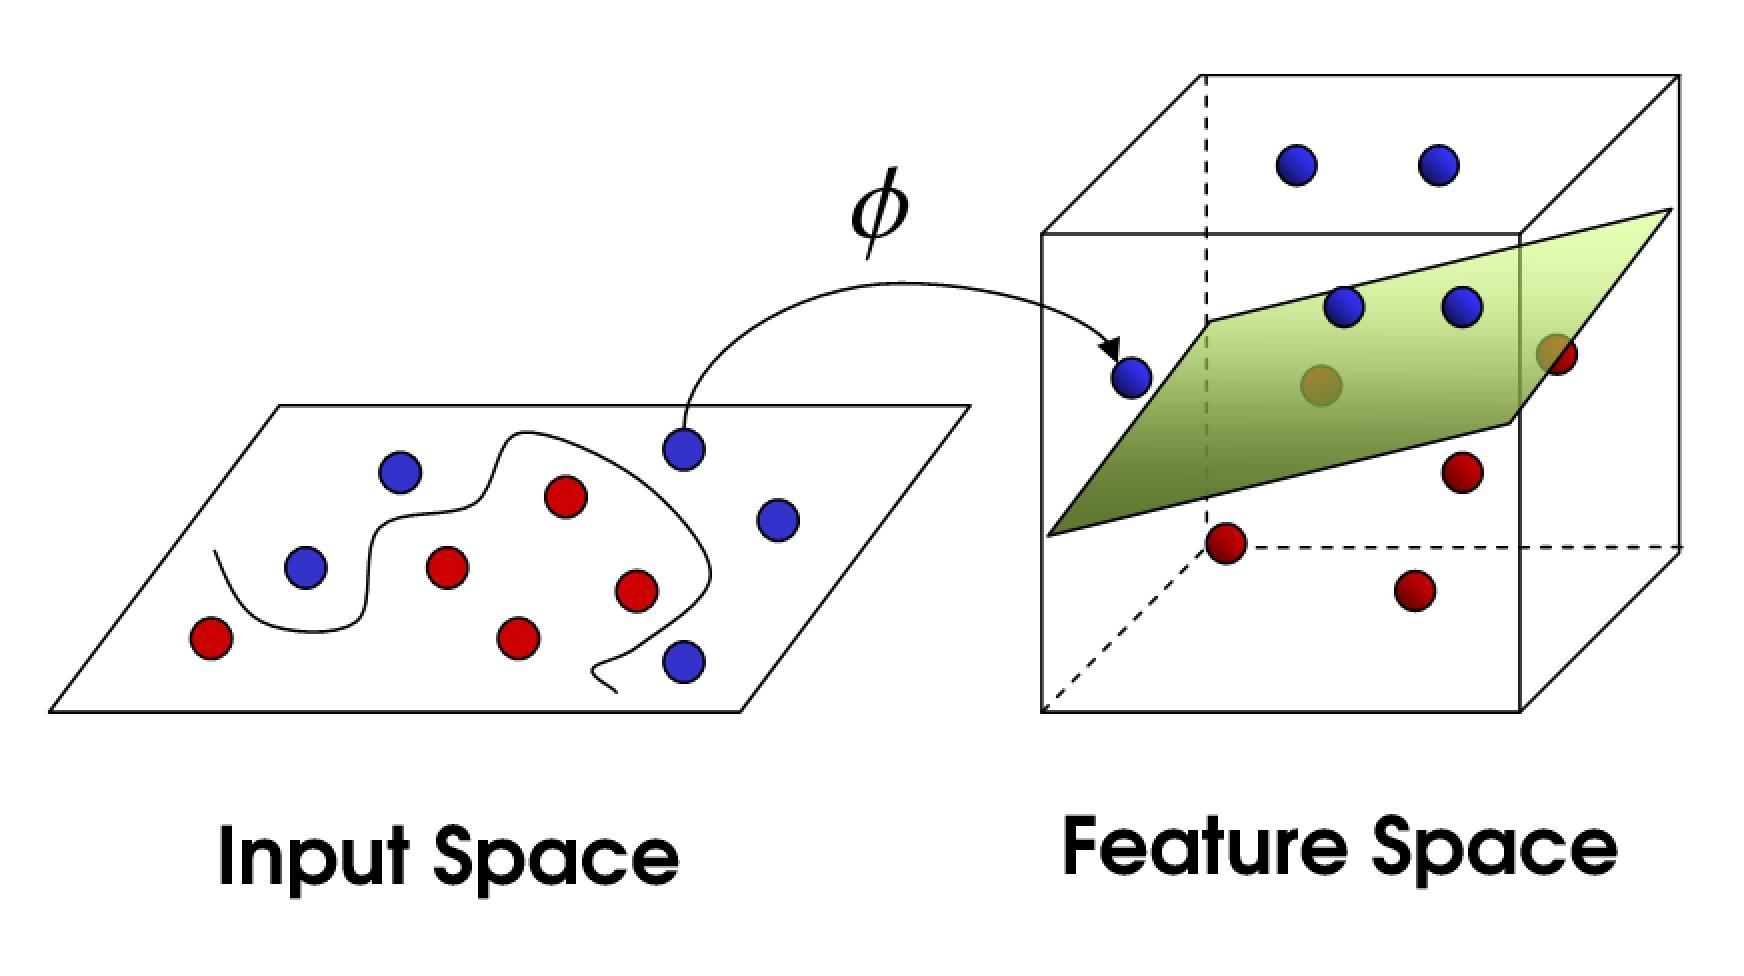

图3 SVM核函数的基本思想

        最初的SVM只能用来解决二分类问题，当面临一个多分类问题时，SVM的策略时将其转换为若干个等价的二分类问题， 具体可以分为以下两类：

- **One against All（一对多）：**对于有 *K* 个类的分类问题，创建 *K* 个SVM模型。对于每一个模型 *k*，将第 *k* 类的数据作为正类，其余所有类的数据合并作为负类。训练每个SVM，使其能够区分第 *k* 类和其它类别。在对某个样本预测时，将样本分别导入*K* 个模型当中，通过得到的结果选择模型（理想情况为有且只有一个模型报出的值为+1） ；  

- **One against One（一对一）：** 对于有 *K* 个类的分类问题，创建 *K*(*K*−1)/2 个SVM模型，每个模型针对一对类别。对于每一对类别 (*i*,*j*)，训练一个SVM，使其能够区分这两个类别。训练过程中只使用属于这两个类别的数据。对于一个新的样本，将其分别输入这些模型。每个模型对样本进行分类，选择一个类别。使用投票机制，每个模型的选择都相当于一票，最终选择得票最多的类别作为预测结果。

        两种策略之间的区别主要包括：

- **模型数量：One against All**需要创建 *K* 个模型，而**One against One**需要创建*K*(*K*−1)/2 个模型。因此，对于类别数较多的情况，**One against One**需要更多的模型。

- **训练数据：One against All**的每个模型使用所有类别的数据，而**One against One**的每个模型只使用两个类别的数据。

- **计算复杂性：One against All**的每个模型可能需要更长的训练时间，因为它需要处理更多的数据。**One against One**虽然模型多，但每个模型的训练数据量较少，训练可能更快。

- **预测性能：One against One**通常被认为在多类别问题上比**One against All**更精确，特别是当类别非常不平衡时。

        为了利用SVM解决回归拟合方面的问题，在SVM分类的基础上引入了 不敏感损失函数，从而得到了回归型支持向量机（Support Vector Machine for Regression，SVR）。SVM应用于回归拟合分析时，其基本思想不再是寻找一个最优分类面使得两类样本分开，而是寻找一个最优分类面**使得所有训练样本离该最优分类面的误差最小**，如图4所示。

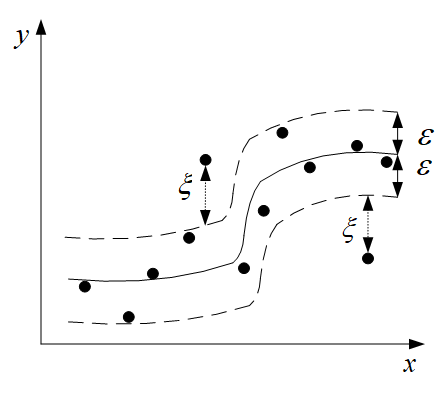

图4 SVR的基本思想                    

## 5.2 案例1：基于SVM的回归拟合——混凝土强度预测

- **数据集导入**

        数据文件concrete_data.mat文件中的变量attributes和strength分别对应103个混凝土样本的组成及立方米抗压强度，每列对应一个样本。

%% 导入数据
load concrete_data.mat

- **训练集/测试集划分**

        不失一般性，这里依然采用随机的方法产生训练集和测试集，即随机选取k（k$<103$）个样本作为训练集，剩余的103-k个样本作为测试集用来对模型的性能进行评价。

% 随机产生训练集和测试集
n = randperm(size(attributes,2));
k = 55;
% 训练集——k个样本
p_train = attributes(:,n(1:k))';
t_train = strength(:,n(1:k))';
% 测试集——103-k个样本
p_test = attributes(:,n(k+1:end))';
t_test = strength(:,n(k+1:end))';

- **数据归一化处理**

% 训练集
[pn_train,inputps] = mapminmax(p_train');
pn_train = pn_train';
pn_test = mapminmax('apply',p_test',inputps);
pn_test = pn_test';
% 测试集
[tn_train,outputps] = mapminmax(t_train');
tn_train = tn_train';
tn_test = mapminmax('apply',t_test',outputps);
tn_test = tn_test';

-  **SVM模型创建/训练**

% 寻找最佳c参数/g参数（网格搜索法）
[c,g] = meshgrid(-10:0.5:10,-10:0.5:10);
[m,n] = size(c);
cg = zeros(m,n);
eps = 10^(-4);
v = 5;      % 交叉验证折数
bestc = 0;
bestg = 0;
error = Inf;
for i = 1:m
    for j = 1:n
        cmd = ['-v ',num2str(v),' -t 2',' -c ',num2str(2^c(i,j)),' -g ',num2str(2^g(i,j) ),' -s 3 -p 0.1'];
        cg(i,j) = svmtrain(tn_train,pn_train,cmd);
        if cg(i,j) < error
            error = cg(i,j);
            bestc = 2^c(i,j);
            bestg = 2^g(i,j);
        end
        if abs(cg(i,j) - error) <= eps && bestc > 2^c(i,j)
            error = cg(i,j);
            bestc = 2^c(i,j);
            bestg = 2^g(i,j);
        end
    end
end
% 创建/训练SVM  
cmd = [' -t 2',' -c ',num2str(bestc),' -g ',num2str(bestg),' -s 3 -p 0.01'];
model = svmtrain(tn_train,pn_train,cmd);

- **SVM仿真预测**

%% SVM仿真预测
[Predict_1,error_1] = svmpredict(tn_train,pn_train,model);

Mean squared error = 0.000394952 (regression)
Squared correlation coefficient = 0.998013 (regression)


[Predict_2,error_2] = svmpredict(tn_test,pn_test,model);

Mean squared error = 0.00482963 (regression)
Squared correlation coefficient = 0.981665 (regression)


% 反归一化
predict_1 = mapminmax('reverse',Predict_1,outputps);
predict_2 = mapminmax('reverse',Predict_2,outputps);
% 结果对比
result_1 = [t_train predict_1];
result_2 = [t_test predict_2];

- ** 绘图**

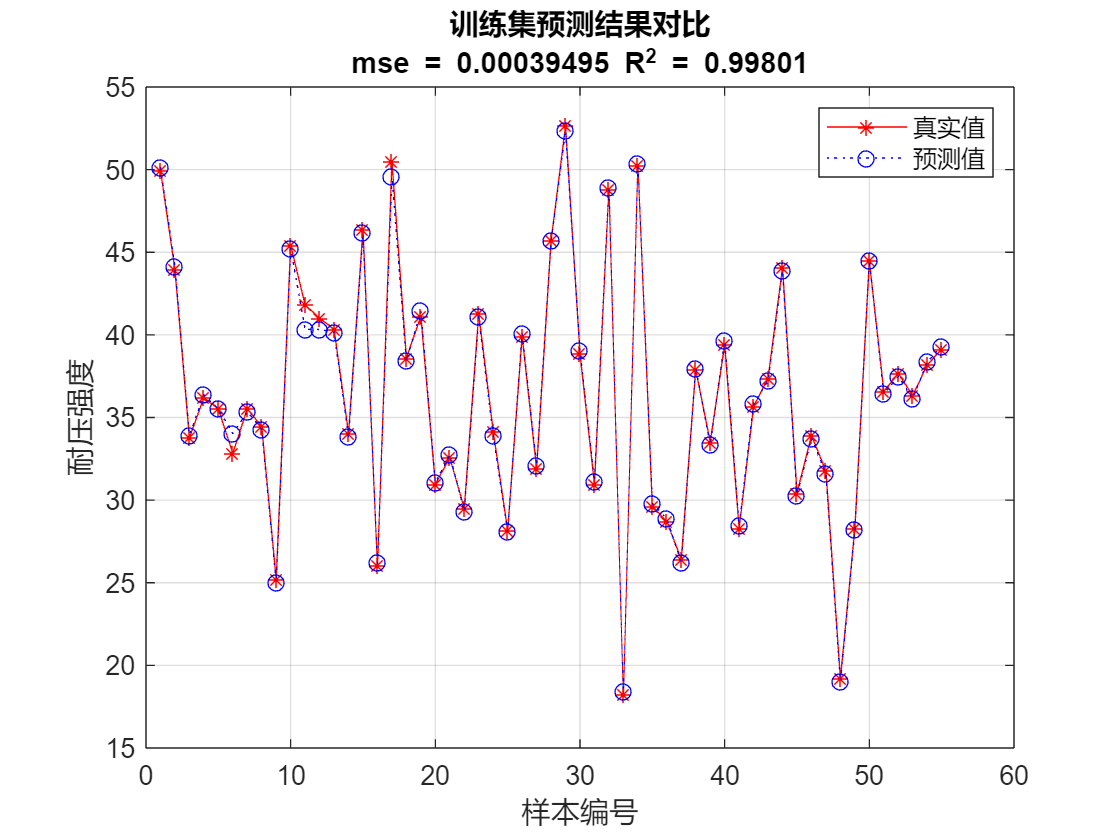

%% 绘图
figure(1)
plot(1:length(t_train),t_train,'r-*',1:length(t_train),predict_1,'b:o')
grid on
legend('真实值','预测值')
xlabel('样本编号')
ylabel('耐压强度')
string_1 = {'训练集预测结果对比';
           ['mse = ' num2str(error_1(2)) ' R^2 = ' num2str(error_1(3))]};
title(string_1)

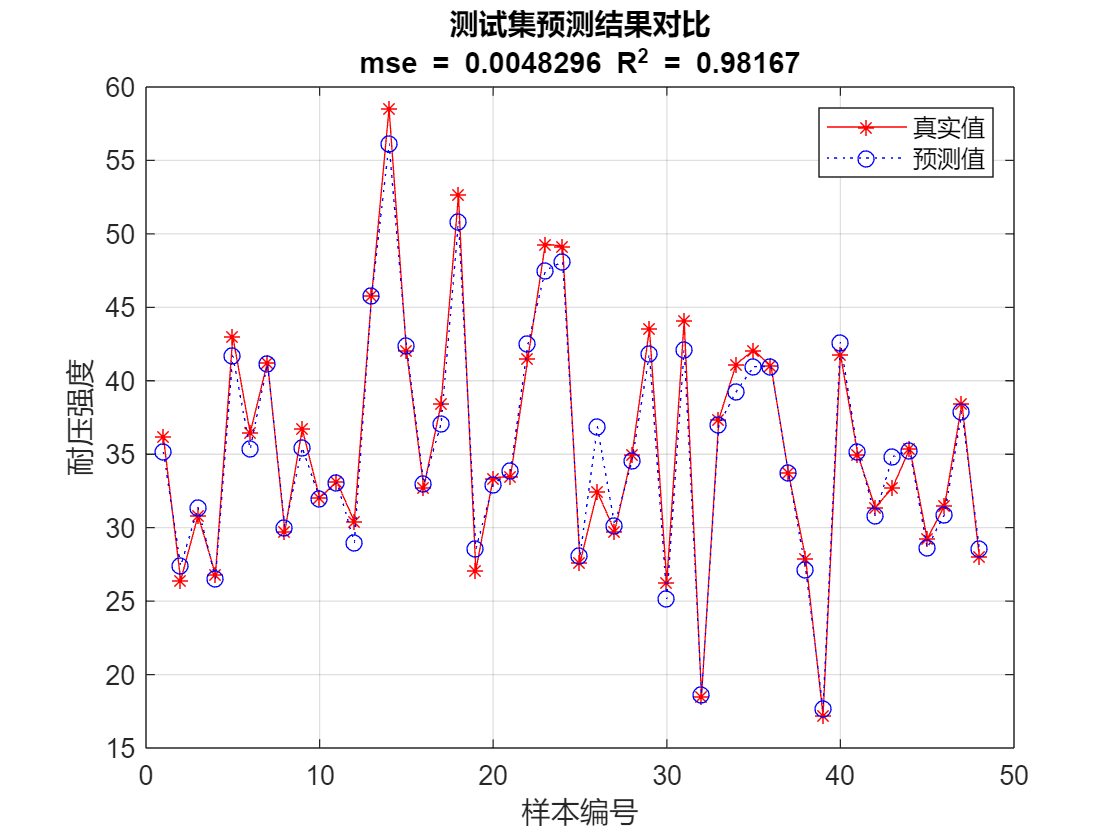

figure(2)
plot(1:length(t_test),t_test,'r-*',1:length(t_test),predict_2,'b:o')
grid on
legend('真实值','预测值')
xlabel('样本编号')
ylabel('耐压强度')
string_2 = {'测试集预测结果对比';
           ['mse = ' num2str(error_2(2)) ' R^2 = ' num2str(error_2(3))]};
title(string_2)

## **5.3 案例2**：基于SVM的分类识别——人脸朝向识别

- **人脸特征向量提取**

% 人数
M = 10;

% 人脸朝向类别数
N = 5; 

% 特征向量提取
pixel_value = feature_extraction(M,N);

- **归一化**

pixel_value = mapminmax(pixel_value);

- **训练集/测试集划分      **

% 产生图像序号的随机序列
rand_label = randperm(M*N);  

% 人脸朝向标号
direction_label = repmat(1:N,1,M);

% 训练集
rand_train = rand_label(1:30);
Train = pixel_value(rand_train,:);
Train_label = direction_label(rand_train)';

% 测试集
rand_test = rand_label(31:end);
Test = pixel_value(rand_test,:);
Test_label = direction_label(rand_test)';

- **训练SVM模型**

model = svmtrain(Train_label,Train,'-c 2 -g 0.05');

- **SVM模型预测**

[predict_label,accuracy] = svmpredict(Test_label,Test,model);

Accuracy = 100% (20/20) (classification)


result_svm = [Test_label';predict_label']

result_svm =      4     1     5     3     4     5     1     2     1     2     2     3     3     3     4     5     4     1     4     5
     4     1     5     3     4     5     1     2     1     2     2     3     3     3     4     5     4     1     4     5


## **Appendix：特征提取子函数**

function pixel_value = feature_extraction(m,n)
        
    pixel_value = zeros(m*n, 8);
    sample_number = 0;

    % 遍历每个人
    for i = 1:m
        % 遍历每个朝向
        for j = 1:n
            % 读取图像
            str = strcat('Images\',num2str(i),'_',num2str(j),'.bmp');
            img = imread(str);

            % 边缘提取
            img_edge = edge(img,'Sobel');

            % 提取特征
            [rows, cols] = size(img);
            sub_rows = floor(rows/6);
            sub_cols = floor(cols/8);
            sample_number = sample_number + 1;
            for subblock_i = 1:8
                for ii = sub_rows+1:2*sub_rows
                    for jj = (subblock_i-1)*sub_cols+1:subblock_i*sub_cols
                        pixel_value(sample_number,subblock_i) = ...
                            pixel_value(sample_number,subblock_i) + img_edge(ii,jj);
                    end
                end
            end
        end
    end
    
end